# Sample Homework 4

Math 3607, Autumn 2021

Tae Eun Kim.3562

clear

## Problem 1. Tracing a satellite

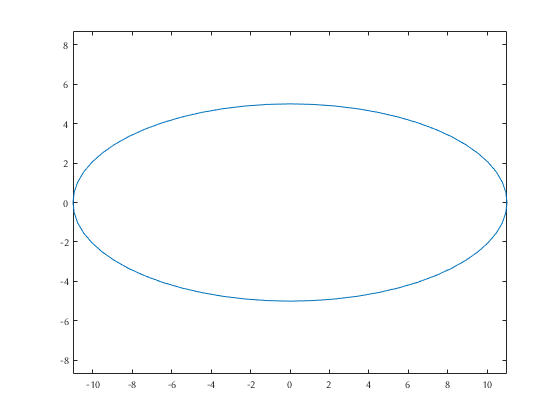

R = 8; r = 3;
theta = linspace(0, 2*pi, 61);
x = (R+r)*cos(theta);
y = (-R+r)*sin(theta);

clf
plot(x,y)
axis equal

Animate it!

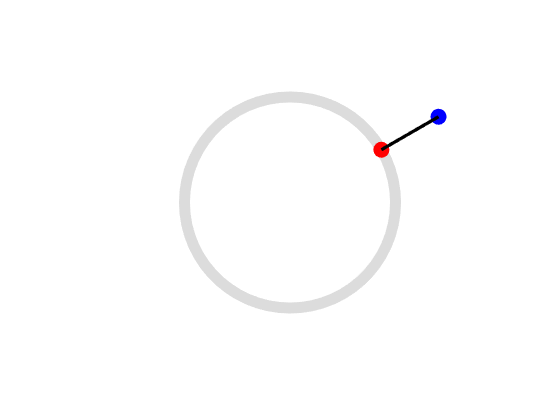

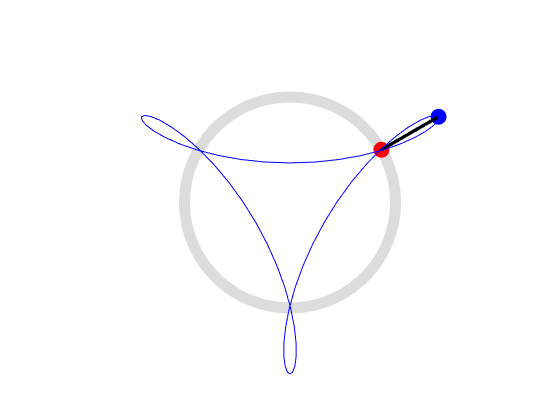

R = 8; r = 5; 
phi = pi/6;  % angular offset
nrpt = 61;
theta = linspace(0, 2*pi, nrpt);
xa = R*cos(-theta+phi);
ya = R*sin(-theta+phi);
x = xa + r*cos(2*theta+phi);
y = ya + r*sin(2*theta+phi);
clf
for j = 1:nrpt
    plot(xa, ya, 'Color', [220,220,220]/255, 'LineWidth', 10)
    hold on
    plot(xa(j), ya(j), 'r.', 'MarkerSize', 50)    % particle A
    plot(x(j), y(j), 'b.', 'MarkerSize', 50)      % particle B
    plot([xa(j) x(j)], [ya(j) y(j)], 'k', 'LineWidth', 3)
    plot(x(1:j), y(1:j), 'b')
    axis equal, axis([-13 13 -13 13]), axis off
    drawnow
    hold off
end

## Problem 2. Spiral triangles

(a) 

Script from the problem.

m = 21; d_angle = 4.5; d_rot = 90;
th = linspace(0, 360, 4) + d_rot;
V = [cosd(th);
     sind(th)];
C = colormap(hsv(m));

R = [cosd(d_angle) -sind(d_angle);
     sind(d_angle) cosd(d_angle)];
hold off

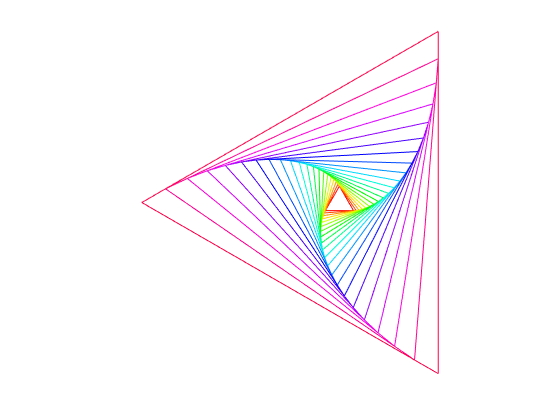

for i = 1:m
  if i > 1
      V = s*R*V;
  end
  plot(V(1,:), V(2,:), 'Color', C(i,:))
  hold on
end
set(gcf, 'Color', 'w')
axis equal, axis off

(b)

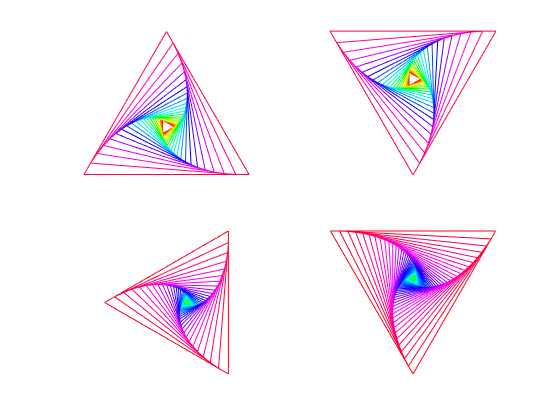

clf
subplot(2, 2, 1), spiralTriangle(21, 4.5, 0);
subplot(2, 2, 2), spiralTriangle(21, -4.5, 0);
subplot(2, 2, 3), spiralTriangle(41, 4.5, 0);
subplot(2, 2, 4), spiralTriangle(61, 3, 90);

## Problem 3. Exploring floating-point numbers

### `fp2ieee.m`

help fp2ieee

  calculates the IEEE representation of a floating-point number in binary
  input: x = floating-point number
  output: ieee.bits = (structure) IEEE representation, i.e., 64 bits of 0's and 1's
              .split = IEEE representation separated for easier reading
              .sci = scientific notation:
                      +- 1.xxxxx... 2^exponent or
                      +- 0.xxxxx... 2^(-1023)
              .sign = +1  if x >= 0
                    = -1  if x < 0



Example

fp2ieee(2+6*eps)

ans = struct with fields:
     sign: 1
     bits: '0100000000000000000000000000000000000000000000000000000000000011'
      sci: '+1.0000000000000000000000000000000000000000000000000011 x 2^1'
    split: '0|100 0000 0000|0000 0000 0000 0000 0000 0000 0000 0000 0000 0000 0000 0000 0011'

### `floatgui.m`

help floatgui

 floatgui  Show structure of floating point numbers.
   The set of positive model floating point numbers is determined
   by three parameters: t, emin, and emax.  It is the set of rational
   numbers of the form x = (1+f)*2^e where f = (integer)/2^t,
   0 <= f < 1, e = integer, and emin <= e <= emax.
 
   IEEE 754 double precision has t = 52, emin = -1022, emax = 1023.



## Problem 4. Catastrophic cancellation

help log1p

 log1p  Compute LOG(1+X) accurately.
    log1p(X) computes LOG(1+X), without computing 1+X for small X.
    Complex results are produced if X < -1.
 
    For small real X, log1p(X) should be approximately X, whereas the
    computed value of LOG(1+X) can be zero or have high relative error.
 
    See also log, expm1.

    Documentation for log1p



log(1+x)


'log' is a built-in function.


## Problem 5. Inversion of hyperbolic cosine

## Functions Used

function V = spiralTriangle(m, d_angle, d_rot)
% SPIRALGON plots spiraling equilateral triangles
% input:   m = the number of triangles
%          d_angle = the degree angle between successive triangle
%          (can be positive or negative)
%          d_rot = the degree angle by which the innermost triangle
%                  is rotated
% output:  V = the vertices of the outermost triangle

th = linspace(0, 360, 4) + d_rot;
V = [cosd(th);
    sind(th)];
C = colormap(hsv(m));
s = sind(150 - abs(d_angle))/sind(30);
R = [cosd(d_angle) -sind(d_angle);
    sind(d_angle) cosd(d_angle)];
hold off
for i = 1:m
    if i > 1
        V = s*R*V;
    end
    plot(V(1,:), V(2,:), 'Color', C(i,:))
    hold on
end
set(gcf, 'Color', 'w')
axis equal, axis off
end